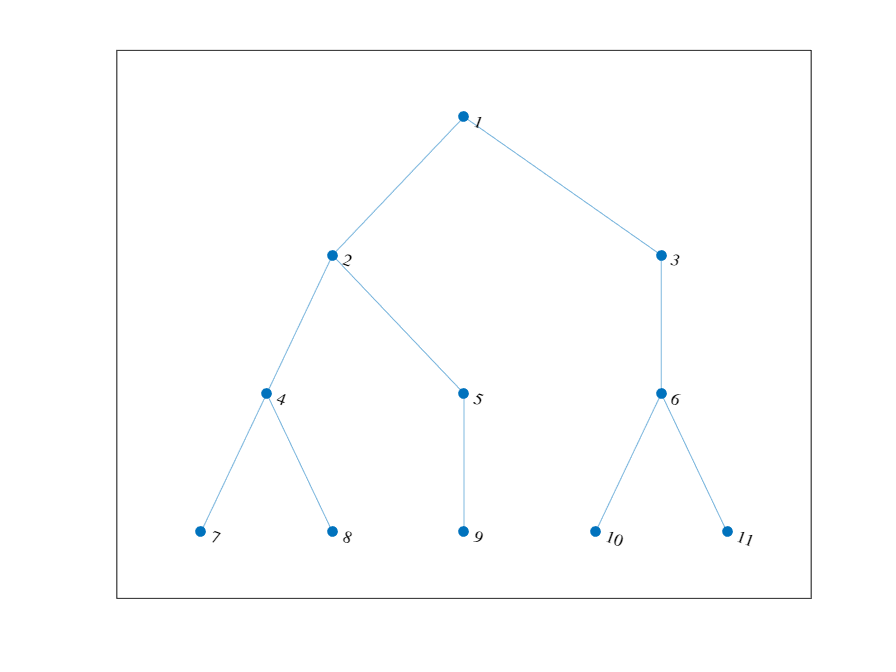

% Define a list of branches representing the original graph
branches = [1 2; 1 3; 2 4; 2 5; 3 6; 4 7; 4 8; 5 9; 6 10; 6 11];
N = max(max(branches));
adjList = sparse([branches(:, 1), branches(:, 2)], [branches(:, 2), branches(:, 1)], 1, N, N);
adjMat = full(adjList);
G = graph(adjMat);
plot(G)

% Define the index of the branch to cut
cutIndex = 2;

% Split the list of branches into two sub-lists at the cutIndex
[subList1, subList2] = splitapply(@(x) {x(1:cutIndex,:), x(cutIndex:end,:)}, branches, 1);

Error using splitapply
Applying the function '@(x){x(1:cutIndex,:),x(cutIndex:end,:)}' to the 1st group of data generated the following error:

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.


% Add the cut branch to both sub-lists
cutBranch = branches(cutIndex,:);
subList1 = [subList1; cutBranch];
subList2 = [cutBranch; subList2];

% Create the two new graphs from the two sub-lists
graph1 = graph(subList1(:,1), subList1(:,2));
graph2 = graph(subList2(:,1), subList2(:,2));

plot(graph1)
plot(graph2)
